Bewegungsgleichung:

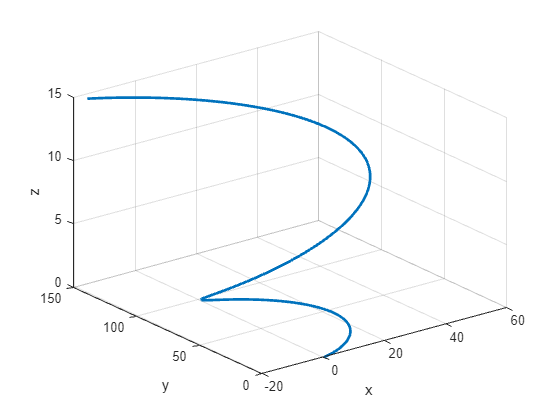

R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.1 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;
figure;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

Gemessene Werte:

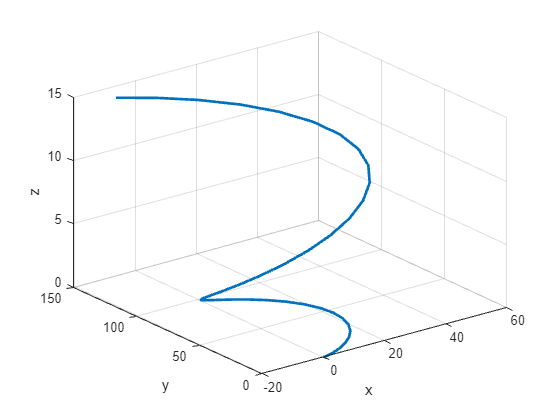

R_measured = extract_every_third_column(R);
figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% y = awgn(R_measured,5);
% 
% figure;
% plot3(y(1,:), y(2,:), y(3,:), 'LineWidth', 2);
% xlabel('x');
% ylabel('y');
% zlabel('z');
% grid on;


R_measured(3,:)

ans =          0    0.0095    0.0379    0.0852    0.1515    0.2367    0.3409    0.4640    0.6060    0.7670    0.9469    1.1458    1.3636    1.6003    1.8560    2.1306    2.4242    2.7367    3.0681    3.4185    3.7878    4.1760    4.5832    5.0093    5.4544    5.9184    6.4014    6.9032    7.4241    7.9638    8.5225    9.1001    9.6967   10.3122   10.9467   11.6001   12.2724   12.9637   13.6739   14.4030


for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end
R_measured(3,:)

ans =    -1.6579   -0.9406    1.2419   -1.7979    1.8669    1.1581    0.2953    0.7781   -0.4448    0.6024    2.7993    1.3330    1.4481    0.5267    1.8116    2.6269    3.1407    2.3187    2.5379    5.3704    1.9387    5.7167    6.2364    6.1941    3.8493    4.9659    5.7428    7.6221    5.9703    8.8487    6.9496    9.7152    9.6734   11.4284   11.8068   13.2150   13.8361   12.3003   14.4689   13.1943


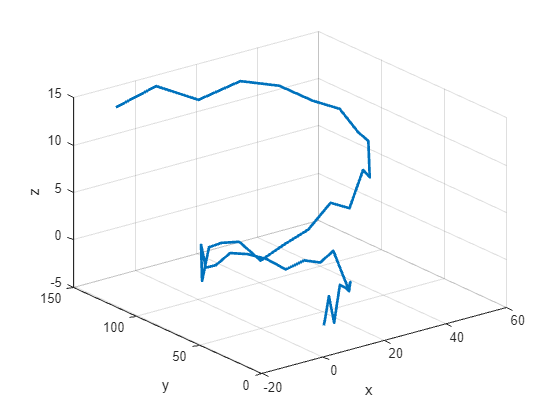

figure;
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'LineWidth', 2);
xlabel('x');
ylabel('y');
zlabel('z');
grid on;

% Gegebene 3D-Punkte (X, Y, Z)
% R_measured = 3x20
points = transpose(R_measured)

points =          0         0   -1.6579
    0.4692    0.0529   -0.9406
    1.8277    0.4155    1.2419
    3.9327    1.3682   -1.7979
    6.5599    3.1358    1.8669
    9.4238    5.8647    1.1581
   12.2030    9.6079    0.2953
   14.5692   14.3176    0.7781
   16.2176   19.8459   -0.4448
   16.8958   25.9553    0.6024



% Zeitpunkte für die Punkte (optional)
% t = 1x200
t_measured = extract_every_third_column(t)

t_measured =          0    0.5025    1.0050    1.5075    2.0101    2.5126    3.0151    3.5176    4.0201    4.5226    5.0251    5.5276    6.0302    6.5327    7.0352    7.5377    8.0402    8.5427    9.0452    9.5477   10.0503   10.5528   11.0553   11.5578   12.0603   12.5628   13.0653   13.5678   14.0704   14.5729   15.0754   15.5779   16.0804   16.5829   17.0854   17.5879   18.0905   18.5930   19.0955   19.5980


% time = 20x1
time = transpose(t_measured)

time =          0
    0.5025
    1.0050
    1.5075
    2.0101
    2.5126
    3.0151
    3.5176
    4.0201
    4.5226




% Berechnung der Geschwindigkeit
velocityX = diff(points(:, 1)) ./ diff(time);
velocityY = diff(points(:, 2)) ./ diff(time);
velocityZ = diff(points(:, 3)) ./ diff(time);

% Geschwindigkeitsvektor erstellen
% velocityVector = [VX1, VY1, VZ1;
%                   VX2, VY2, VZ2;
%                   VX3, VY3, VZ3;
%                   ...];
velocityVector = [velocityX, velocityY, velocityZ];

% Berechnung der Beschleunigung
accelerationX = diff(velocityVector(:, 1)) ./ diff(time(1:end-1));
accelerationY = diff(velocityVector(:, 2)) ./ diff(time(1:end-1));
accelerationZ = diff(velocityVector(:, 3)) ./ diff(time(1:end-1));

% Beschleunigungsvektor erstellen
accelerationVector = [accelerationX, accelerationY, accelerationZ];


% Ergebnis ausgeben
disp(velocityVector);

    0.9337    0.1052    1.4275
    2.7035    0.7215    4.3433
    4.1888    1.8961   -6.0493
    5.2281    3.5174    7.2930
    5.6992    5.4304   -1.4106
    5.5306    7.4490   -1.7168
    4.7087    9.3723    0.9607
    3.2803   11.0014   -2.4336
    1.3497   12.1576    2.0840
   -0.9288   12.6975    4.3718
   -3.3623   12.5270   -2.9179
   -5.7349   11.6109    0.2291
   -7.8250    9.9781   -1.8336
   -9.4241    7.7211    2.5569
  -10.3542    4.9914    1.6224
  -10.4842    1.9891    1.0226
   -9.7430   -1.0515   -1.6358
   -8.1271   -3.8792    0.4360
   -5.7047   -6.2461    5.6368
   -2.6133   -7.9268   -6.8290
    0.9482   -8.7378    7.5181
    4.7322   -8.5539    1.0341
    8.4593   -7.3209   -0.0841
   11.8386   -5.0624   -4.6662
   14.5896   -1.8828    2.2221
   16.4640    2.0380    1.5460
   17.2660    6.4537    3.7399
   16.8697   11.0679   -3.2872
   15.2313   15.5533    5.7281
   12.3969   19.5749   -3.7793
    8.5025   22.8144    5.5036
    3.7683   24.9941   -0.0831
   -1.51

% Ergebnis ausgeben
disp(accelerationVector);

    3.5218    1.2265    5.8023
    2.9559    2.3373  -20.6811
    2.0682    3.2265   26.5511
    0.9374    3.8069  -17.3202
   -0.3356    4.0170   -0.6093
   -1.6355    3.8272    5.3283
   -2.8425    3.2421   -6.7547
   -3.8420    2.3007    8.9901
   -4.5342    1.0743    4.5527
   -4.8427   -0.3393  -14.5064
   -4.7215   -1.8229    6.2625
   -4.1594   -3.2494   -4.1048
   -3.1821   -4.4914    8.7372
   -1.8508   -5.4321   -1.8598
   -0.2588   -5.9746   -1.1936
    1.4751   -6.0507   -5.2901
    3.2156   -5.6273    4.1229
    4.8204   -4.7101   10.3495
    6.1519   -3.3445  -24.8069
    7.0874   -1.6139   28.5508
    7.5301    0.3658  -12.9032
    7.4169    2.4538   -2.2254
    6.7249    4.4943   -9.1183
    5.4745    6.3275   13.7077
    3.7301    7.8023   -1.3455
    1.5960    8.7873    4.3659
   -0.7888    9.1822  -13.9841
   -3.2603    8.9259   17.9406
   -5.6405    8.0030  -18.9199
   -7.7499    6.4465   18.4730
   -9.4210    4.3376  -11.1175
  -10.5106    1.8013    7.1154
  -10.91

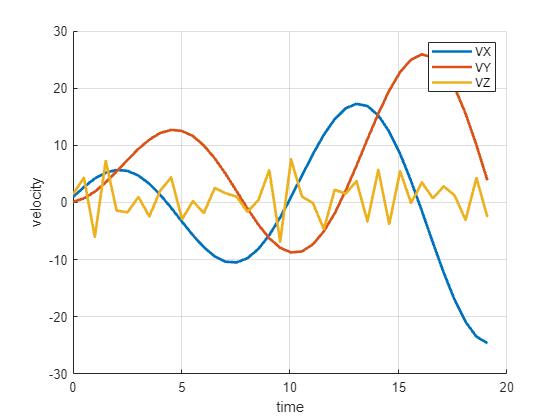

velocityVector = transpose(velocityVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, velocityVector(1,:), 'LineWidth', 2);
plot(time, velocityVector(2,:), 'LineWidth', 2);
plot(time, velocityVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('velocity');
grid on;

legend('VX', 'VY', 'VZ');

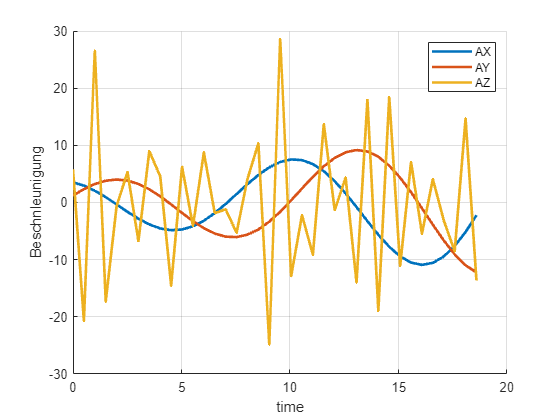

accelerationVector = transpose(accelerationVector);
time = transpose(time(1:end-1));

figure;
hold on;

plot(time, accelerationVector(1,:), 'LineWidth', 2);
plot(time, accelerationVector(2,:), 'LineWidth', 2);
plot(time, accelerationVector(3,:), 'LineWidth', 2);

xlabel('time');
ylabel('Beschnleunigung');
grid on;

legend('AX', 'AY', 'AZ');

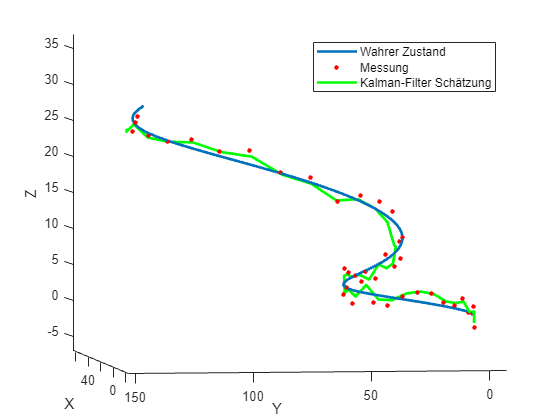

% Gegebenes Beispiel
R_0 = [0; 0; 0];
V_0 = [0; 0; 0];
t = linspace(0, 20, 200);
A = [5 * cos(t/2); 5 * sin(t/2); 0.2 * ones(size(t/2))]; % Erhöhte Beschleunigung
V = cumtrapz(t/2, A, 2) + V_0;

R = R_0 + cumtrapz(t/2, V, 2) + 0.5 * cumtrapz(t/2, A, 2) .* t;

R_measured = extract_every_third_column(R);
for i=1:length(R_measured(3,:))
    % Zufällige Werte zwischen -2 und 2 generieren
    randomValues = 4 * rand(1, 1) - 2;
    R_measured(3,i) = R_measured(3,i) + randomValues;
end

% Kalman-Filter Parameter
dt = 0.5;                % Abtastzeit
A_kalman = [1 dt dt^2/2; 0 1 dt; 0 0 1];       % Zustandsübergangsmatrix
B_kalman = [dt^3/6; dt^2/2; dt];               % Steuerungsmatrix (Beschleunigung)
C_kalman = eye(3);                             % Messmatrix (direkte Messung von X, Y, Z)
Q_kalman = diag([0.8, 0.8, 0.8]);              % Prozessrauschkovarianz
R_kalman = diag([0.3, 0.5, 0.5]);              % Messrauschkovarianz

% Initialisierung
x_kalman = zeros(3, length(R_measured));
P_kalman = zeros(3, 3, length(R_measured));

% Schätzung mit Kalman-Filter
for i = 1:length(R_measured)
    % Vorhersage
    if i == 1
        x_pred = [0; 0; 0];
        P_pred = eye(3);
    else
        x_pred = A_kalman * x_kalman(:, i-1) + B_kalman .* A(:, i-1);
        P_pred = A_kalman * P_kalman(:, :, i-1) * A_kalman' + Q_kalman;
    end
    
    % Korrektur
    K = P_pred * C_kalman' / (C_kalman * P_pred * C_kalman' + R_kalman);
    x_kalman(:, i) = x_pred + K * (R_measured(:, i) - C_kalman * x_pred);
    P_kalman(:, :, i) = (eye(3) - K * C_kalman) * P_pred;
end

% Ergebnisse anzeigen
figure;
hold on;
plot3(R(1,:), R(2,:), R(3,:), 'LineWidth', 2);
plot3(R_measured(1,:), R_measured(2,:), R_measured(3,:), 'r.', 'MarkerSize', 10);
plot3(x_kalman(1,:), x_kalman(2,:), x_kalman(3,:), 'g-', 'LineWidth', 2);
legend('Wahrer Zustand', 'Messung', 'Kalman-Filter Schätzung');
xlabel('X');
ylabel('Y');
zlabel('Z');
view(3);

function new_array = extract_every_third_column(R)
    new_array = R(:, 1:5:end);
end